% Aim 1: Heatmap of all neurons vs odors
nwb = nwbRead('MATLAB/Neural signal project/sub-8_ses-20200204T180138_ophys.nwb');

ophys = get(nwb.processing, 'ophys');
fluorescence = get(ophys.nwbdatainterface, 'Fluorescence');

roi_response = get(fluorescence.roiresponseseries, 'Plane_0');
dff = roi_response.data.load();              
timestamps = roi_response.timestamps.load(); 


odor = get(nwb.stimulus_presentation, 'odor');
stim_timestamps = odor.timestamps.load();  
stim_labels = odor.data.load();            

% Ensure stim_labels and stim_timestamps are column vectors
stim_labels = stim_labels(:);
stim_timestamps = stim_timestamps(:);

% Detect odor onset indices
odor_onset_idx = find([true; diff(stim_labels) ~= 0]);

% Extract onset times and labels
odor_onset_times = stim_timestamps(odor_onset_idx);
odor_onset_labels = stim_labels(odor_onset_idx);

% Filter out invalid (NaN or background) labels
valid_mask = ~isnan(odor_onset_labels) & odor_onset_labels >= 0;
odor_onset_times = odor_onset_times(valid_mask);
odor_onset_labels = odor_onset_labels(valid_mask);

% Optional: Filter out very short intervals (if needed)
% min_interval = 3; % in seconds
% keep = [true; diff(odor_onset_times) > min_interval];
% odor_onset_times = odor_onset_times(keep);
% odor_onset_labels = odor_onset_labels(keep);

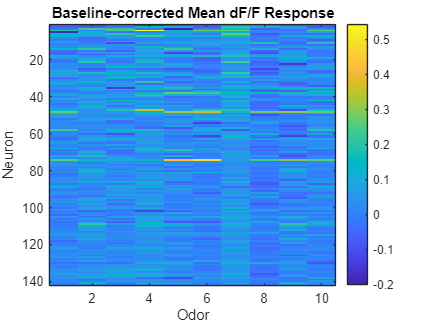


resp_window = [0, 2];         % Response window (after stimulus)
baseline_window = [-1, 0];    % Baseline window (before stimulus)

fps = 1 / median(diff(timestamps));
resp_frames = round(resp_window * fps);
base_frames = round(baseline_window * fps);

n_cells = size(dff, 1);
n_odors = 10;
trial_responses = zeros(n_cells, length(odor_onset_times));

% Calculate baseline-corrected dF/F per trial
for i = 1:length(odor_onset_times)
    t0 = odor_onset_times(i);
    [~, onset_idx] = min(abs(timestamps - t0));
    
    base_idx = onset_idx + base_frames(1):onset_idx + base_frames(2);
    resp_idx = onset_idx + resp_frames(1):onset_idx + resp_frames(2);

    if min(base_idx) < 1 || max(resp_idx) > size(dff, 2)
        trial_responses(:, i) = NaN;
        continue;
    end

    F0 = mean(dff(:, base_idx), 2);
    F_resp = mean(dff(:, resp_idx), 2);
    dff_trial = (F_resp - F0) ./ F0;

    trial_responses(:, i) = dff_trial;
end

% Compute average dF/F for each neuron × odor pair
mean_responses = zeros(n_cells, n_odors);
for odor = 1:n_odors
    idx = find(odor_onset_labels == odor);
    mean_responses(:, odor) = mean(trial_responses(:, idx), 2, 'omitnan');
end

% Plot heatmap of mean dF/F
figure;
imagesc(mean_responses);
xlabel('Odor'); ylabel('Neuron');
title('Baseline-corrected Mean dF/F Response');
colorbar;

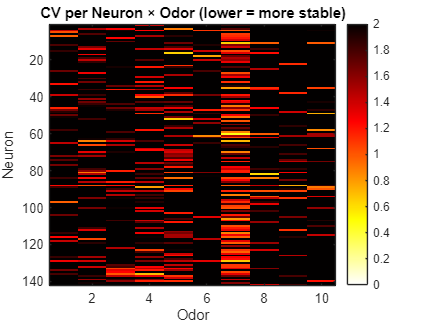


% --- CV matrix per neuron × odor ---
[n_neurons, ~] = size(trial_responses);
CV_per_odor = nan(n_neurons, n_odors);

for neuron = 1:n_neurons
    for odor = 1:n_odors
        idx = find(odor_onset_labels == odor);
        responses = trial_responses(neuron, idx);
        responses = responses(~isnan(responses));

        if numel(responses) >= 3
            mu = mean(responses);
            sigma = std(responses);
            CV_per_odor(neuron, odor) = sigma / (abs(mu) + 1e-6);
        end
    end
end

% Plot CV heatmap
figure;
imagesc(CV_per_odor, [0 2]);  % Adjust color scale as needed
colormap(flipud(hot));        % Lower CV = brighter (more stable)
colorbar;
xlabel('Odor');
ylabel('Neuron');
title('CV per Neuron × Odor (lower = more stable)');


% --- Identify strong & stable responses ---
high_response_threshold = 0.1;  % ΔF/F threshold
max_cv_threshold = 0.8;         % CV threshold

results = [];

for neuron = 1:n_cells
    for odor = 1:n_odors
        trial_idx = find(odor_onset_labels == odor);
        trials = trial_responses(neuron, trial_idx);

        if numel(trials) < 3
            continue;
        end

        mean_dff = mean(trials, 'omitnan');
        std_dff = std(trials, 'omitnan');
        cv_dff = std_dff / (abs(mean_dff) + 1e-6);

        if mean_dff > high_response_threshold && cv_dff < max_cv_threshold
            results = [results; neuron, odor, mean_dff, std_dff, cv_dff];
        end
    end
end

% Display strong & stable combinations
if isempty(results)
    results = nan(0,5);
end

T = array2table(results, ...
    'VariableNames', {'Neuron', 'Odor', 'Mean_dF_F', 'Std_dF_F', 'CV_dF_F'});
disp('✅ Neuron-Odor combinations with strong and stable responses:');

✅ Neuron-Odor combinations with strong and stable responses:


disp(T);

    Neuron    Odor    Mean_dF_F    Std_dF_F    CV_dF_F
    ______    ____    _________    ________    _______

      18        6      0.17857     0.13803     0.77294
      35        7      0.13147     0.10308     0.78404
      49       10      0.16296     0.12075     0.74097
      89        4      0.13561     0.10798     0.79623



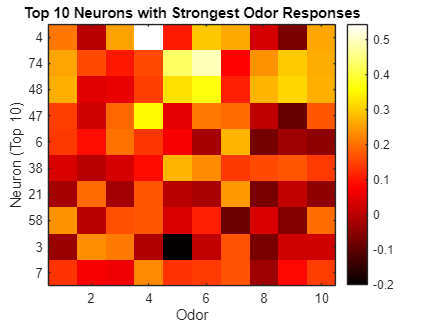


% --- Top 10 neurons by maximum odor response ---
max_response_per_neuron = max(mean_responses, [], 2);
[~, sorted_idx] = sort(max_response_per_neuron, 'descend');
top_n = 10;
top_neuron_idx = sorted_idx(1:min(top_n, length(sorted_idx)));

top10_responses = mean_responses(top_neuron_idx, :);

figure;
imagesc(top10_responses);
xlabel('Odor');
ylabel('Neuron (Top 10)');
yticks(1:length(top_neuron_idx));
yticklabels(top_neuron_idx);
title('Top 10 Neurons with Strongest Odor Responses');
colorbar;
colormap('hot');

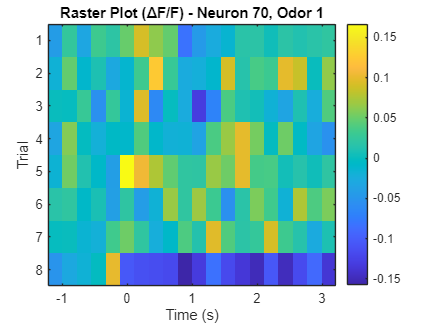

% --- Raster plot and PSTH for a selected neuron and odor ---
neuron_id = 70;    
target_odor = 1;  
window = [-1, 3];  % from -1s to +3s around odor onset

fps = 1 / median(diff(timestamps));
win_frames = round(window(1) * fps):round(window(2) * fps);
t_axis = win_frames / fps;

trial_idx = find(odor_onset_labels == target_odor);
n_trials = length(trial_idx);
raster_data = zeros(n_trials, length(win_frames));

for i = 1:n_trials
    t0 = odor_onset_times(trial_idx(i));
    [~, onset_idx] = min(abs(timestamps - t0));
    idx = onset_idx + win_frames;

    if min(idx) < 1 || max(idx) > length(timestamps)
        raster_data(i, :) = NaN;
        continue;
    end

    % Baseline normalization
    baseline_idx = idx(t_axis < 0);
    F0 = mean(dff(neuron_id, baseline_idx), 'omitnan');
    raster_data(i, :) = (dff(neuron_id, idx) - F0) / F0;
end

% Raster plot (ΔF/F per trial)
figure;
imagesc(t_axis, 1:n_trials, raster_data);
xlabel('Time (s)'); ylabel('Trial');
title(sprintf('Raster Plot (ΔF/F) - Neuron %d, Odor %d', neuron_id, target_odor));
colorbar;

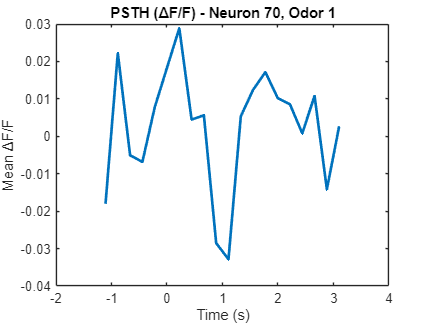


% PSTH (mean ΔF/F across trials)
mean_trace = nanmean(raster_data, 1);
figure;
plot(t_axis, mean_trace, 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Mean ΔF/F');
title(sprintf('PSTH (ΔF/F) - Neuron %d, Odor %d', neuron_id, target_odor));

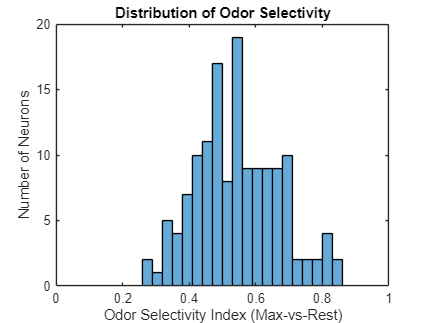


% --- Calculate OSI (Max-vs-Rest version) ---
n_cells = size(mean_responses, 1);
OSI = zeros(n_cells, 1);

for n = 1:n_cells
    responses = mean_responses(n, :);
    
    % Set negative responses to 0 to avoid issues
    responses(responses < 0) = 0;

    [r_max, max_idx] = max(responses);
    rest = responses;
    rest(max_idx) = [];
    r_mean_others = mean(rest, 'omitnan');

    OSI(n) = (r_max - r_mean_others) / (r_max + r_mean_others + 1e-6);
end

% Plot OSI histogram
figure;
histogram(OSI, 20);
xlim([0 1])
xlabel('Odor Selectivity Index (Max-vs-Rest)');
ylabel('Number of Neurons');
title('Distribution of Odor Selectivity');


% --- Top 10 OSI neurons ---
[sorted_osi, sorted_idx] = sort(OSI, 'descend');
top_n = 10;
top_neuron_idx = sorted_idx(1:min(top_n, length(sorted_idx)));
top_osi_values = sorted_osi(1:min(top_n, length(sorted_idx)));

OSI_table = table(top_neuron_idx, top_osi_values, ...
    'VariableNames', {'Neuron', 'Max_vs_Rest_OSI'});
disp('🔍 Top OSI Neurons (Max-vs-Rest):');

🔍 Top OSI Neurons (Max-vs-Rest):


disp(OSI_table);

    Neuron    Max_vs_Rest_OSI
    ______    _______________

     102          0.84433    
      61          0.84193    
      87          0.81343    
      71           0.8103    
      54          0.80505    
       1          0.80389    
      69          0.78749    
      26           0.7777    
      30          0.76837    
     104           0.7577    



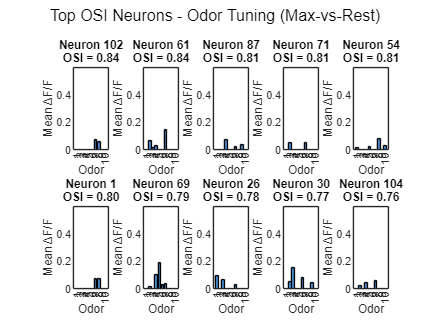


% Plot tuning curves for top OSI neurons
figure;
for i = 1:length(top_neuron_idx)
    subplot(2, ceil(top_n/2), i);
    neuron_id = top_neuron_idx(i);
    bar(mean_responses(neuron_id, :), 'FaceColor', [0.3 0.6 0.9]);
    title(sprintf('Neuron %d\nOSI = %.2f', neuron_id, OSI(neuron_id)));
    xlabel('Odor'); ylabel('Mean ΔF/F');
    ylim([0 max(mean_responses(:))*1.1]);
end
sgtitle('Top OSI Neurons - Odor Tuning (Max-vs-Rest)');

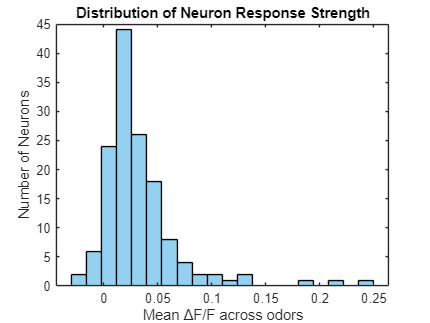


% --- Distribution of Mean and Max ΔF/F ---
mean_strength = mean(mean_responses, 2, 'omitnan');
figure;
histogram(mean_strength, 20, 'FaceColor', [0.3 0.7 0.9]);
xlabel('Mean ΔF/F across odors');
ylabel('Number of Neurons');
title('Distribution of Neuron Response Strength');

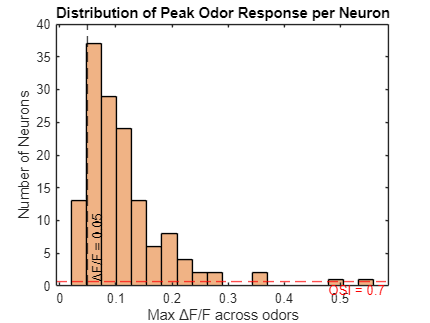


max_strength = max(mean_responses, [], 2);
figure;
histogram(max_strength, 20, 'FaceColor', [0.9 0.5 0.2]);
xlabel('Max ΔF/F across odors');
ylabel('Number of Neurons');
title('Distribution of Peak Odor Response per Neuron');
hold on;
xline(0.05, '--k', 'ΔF/F = 0.05', 'LabelVerticalAlignment','bottom');
yline(0.7, '--r', 'OSI = 0.7', 'LabelVerticalAlignment','bottom');
hold off

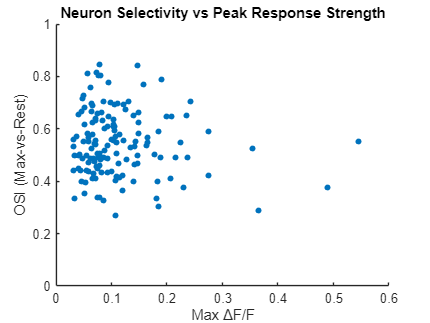


% Scatter plot: Max ΔF/F vs OSI
figure;
scatter(max_strength, OSI, 20, 'filled');
xlabel('Max ΔF/F');
ylabel('OSI (Max-vs-Rest)');
title('Neuron Selectivity vs Peak Response Strength');
ylim([0 1]);

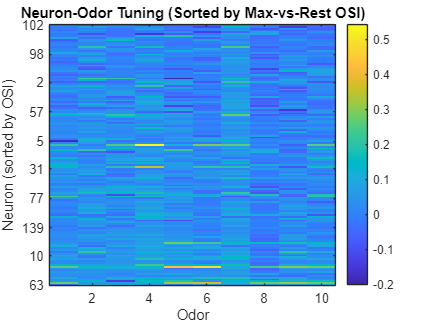


% --- OSI sorted heatmap ---
[~, osi_sorted_idx] = sort(OSI, 'descend');
sorted_mean_responses = mean_responses(osi_sorted_idx, :);

figure;
imagesc(sorted_mean_responses);
xlabel('Odor');
ylabel('Neuron (sorted by OSI)');
title('Neuron-Odor Tuning (Sorted by Max-vs-Rest OSI)');
colorbar;
yticks(round(linspace(1, length(osi_sorted_idx), 10)));
yticklabels(osi_sorted_idx(round(linspace(1, length(osi_sorted_idx), 10))));

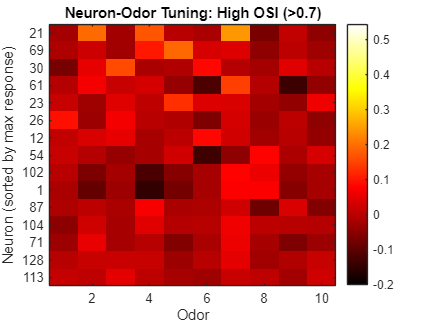

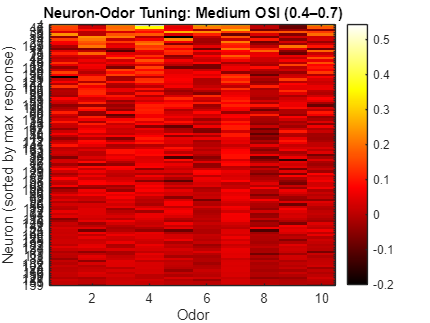

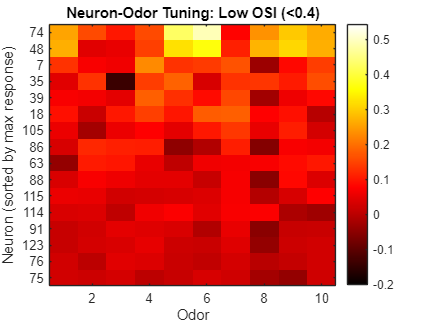


% --- Split heatmaps by OSI groups ---
group_high = find(OSI > 0.7);
group_mid = find(OSI <= 0.7 & OSI >= 0.4);
group_low = find(OSI < 0.4);

groups = {group_high, group_mid, group_low};
group_names = {'High OSI (>0.7)', 'Medium OSI (0.4–0.7)', 'Low OSI (<0.4)'};

cmap_range = [min(mean_responses(:)), max(mean_responses(:))];

for i = 1:3
    idx = groups{i};
    if isempty(idx)
        fprintf('%s group is empty.\n', group_names{i});
        continue;
    end

    data = mean_responses(idx, :);
    max_resp = max(data, [], 2);
    [~, sort_idx] = sort(max_resp, 'descend');
    
    sorted_data = data(sort_idx, :);
    sorted_neuron_ids = idx(sort_idx);

    figure;
    imagesc(sorted_data, cmap_range);
    colormap hot;
    colorbar;
    xlabel('Odor');
    ylabel('Neuron (sorted by max response)');
    title(['Neuron-Odor Tuning: ' group_names{i}]);
    yticks(1:length(sorted_neuron_ids));
    yticklabels(sorted_neuron_ids);
end